This demo demonstrates how to export the geometry to either image (.*bmp*, .*jpeg* or .*png* file formats) or to **ST**ereo**L**ithography (.stl) file, which has a simple file format and can be read in any CAD software or in MATLAB.

clc
clear

Let's open CST project with some geometry. It contains several 3D shapes and a patch (face). Different materials are assigned to the shapes, and color of some shapes has been changed from default material color.

CSTProject = 'CST\Geom_Shapes.cst';  % path and file name
CST = TCSTInterface(CSTProject);     % we can directly pass the project file as an argument to the constructor, or use CST.OpenProject method.

Connected to project "E:\01_Toolboxes\CSTMWS-Matlab-Interface\Demos\CST\Geom_Shapes.cst"


# **Exporting geomertical moded from CST as an image**

Before saving an image, we set the desired view in CST. The argument for the `SetView` method below can be a 1x2 vector [*azimuth* *elevation*] (as for Matlab's `veiw` function), or it can take one of the following values: 

Several values can be also provided as a cell array:

ViewAzEl = [-36 31];  % [azimuth elevation], in deg
CST.SetView({ViewAzEl,'ZoomToStructure'}); % set the desired view angle and zoom to the entire structure

Now, we export the view to the specified image file:

ImgFile = 'Test.png'; % can contain full or relative path
ImgWidthPx  = 400;  % Width of the exported image in pixels 
ImgHeightPx = 400;  % Height of the exported image in pixels
CST.ExportImage(ImgFile, ImgWidthPx, ImgHeightPx);

Plot the image:

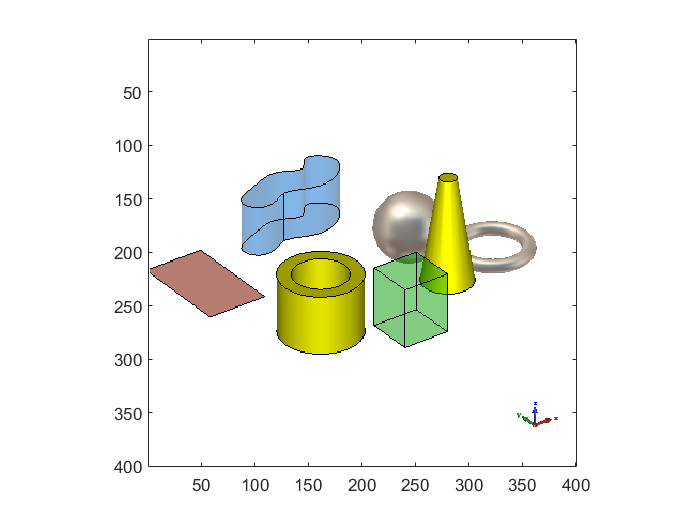

Img = imread(ImgFile);
figure;
image(Img);
axis equal tight;

I don't know if it is a bug of CST or some issue in my computer, but sometimes CST saves black image if the CST application is minimized. If that happened, just restore/maximize the CST app and re-run this demo.

# **Exporting geomertical moded from CST as an STL file**

To export the geometry to an STL file,  the `ExportObjectsToSTL` method is used, which has the following syntax:

where `STLFile` is the STL file name (can be both with full or relative path), and the optional argument pairs `ParName``N`,`ParVal``N` are the following:

- `'Objects',ObjsToExport` - specifies the geometrical objects (solids) which should be exported. By default, all objects will be exported. `ObjsToExport` can be either a string (if only one object shoud be exported) or a cell array of strings (if several objects to be exported). Each object name must contain the component name which it belongs to. For example, in this CST demo project the full name of the `Cone` object is `'Shapes1:Cone'`, and for the `ExtrudedSpline` object it is `'Shapes2/SubComponent:ExtrudedSpline'`.

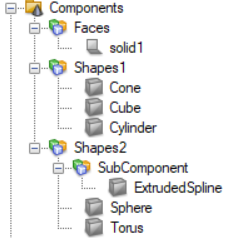

- `'ExportUnits',Units` - Length units, in which the geometry should be exported. The valid values are` 'm', 'cm', 'mm', 'um', 'ft', 'in', 'mil'`. By default, `'mm'` are used.

- `'NormalTolerance',AngleDeg` - CST documentation reads: "*Normal tolerance is the maximum angle between any two surface normals on a facet. Set this option to control accuracy of the exported model compared to the model in the project*." The angle `AngleDeg` is specified in degrees, and must be in range from 1$^\circ$ to 43$^\circ$. By default, CST decides what value to use. Below there are few examples what effect this parameter has on the exported geometry.

- `'SurfaceTolerance',Tol` - CST documentation reads: "*Surface tolerance is the maximum distance between the facet and the part of the surface it is representing. Set this option to control accuracy of the exported model compared to the model in the project.*" The tolerance `Tol` can take values from 0.00001 to 0.1. By default, CST decides what value to use. Below there are few examples what effect this parameter has on the exported geometry.

- `'AppendColorsToObjName',BoolValue` - STL files can be either ASCII or binary. CST exports geometries in the ASCII file format, which allows to specify the name of the exported solid. The interface uses the object full name (like `'Shapes2/SubComponent:ExtrudedSpline')` as the solid name. If the option `'AppendColorsToObjName'` is `true`, the interface tries to obtain exact color and transparency of the objects as they appear in CST, and appends this info to the solid name, e.g. `'Shapes2/SubComponent:ExtrudedSpline COLOR_RGBA={0,0.501961,1,0.5}'`. Leter, this info can be extracted by a custom STL reader to plot the objects like they look in CST. In this demo we will use such a reader.

Here we will use the later option:

STLFile = 'Test.stl'; % can contain full or relative path
CST.ExportObjectsToSTL(STLFile, 'AppendColorsToObjName',true); 

Now we have the STL file. One can use any available reader to get triangulation of objects from it, e.g. Matlab's native `stlread` function. However, in this way the additional color information we have opted to save to the file will be lost (because STL file standard doesn't support colors). Therefore, we will use the custom STL reader TSTLReader, which is also capable to plot the imported solids.

STL = TSTLReader(STLFile);  % read the STL file

Plot the geometry:

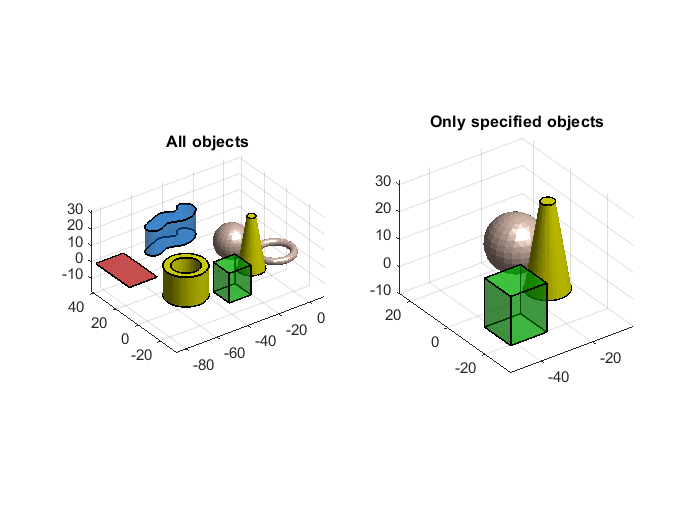

figure;

% plot all imported objects
subplot(1,2,1)
STL.PlotSolid();
axis equal tight; view(ViewAzEl); camlight; grid on; title('All objects');

% plot only specified objects
subplot(1,2,2)
STL.PlotSolid({'Sphere','Cone','Cube'}); % plots objects whose name contains the specified strings
axis equal tight; view(ViewAzEl); camlight; grid on; title('Only specified objects');

One can note not very fine surface approximation of the objects CST uses by default. We can change it by using options `'NormalTolerance'` or `'SurfaceTolerance'` while exporting the STL file:

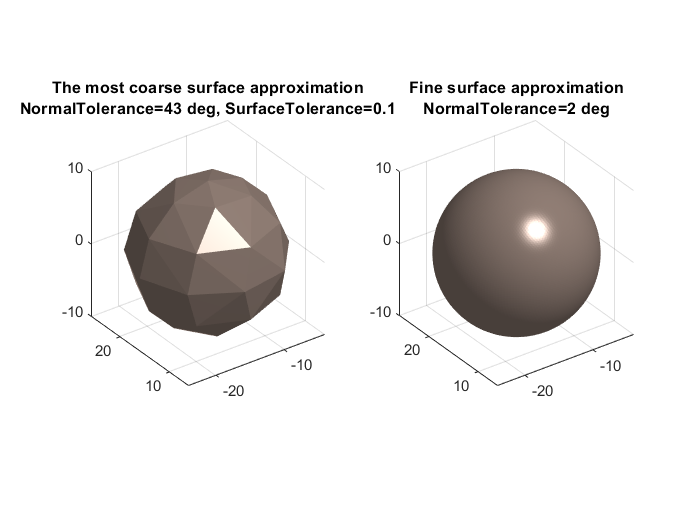

figure;

% the most coarse surface approximation allowed by CST MWS (NormalTolerance=43 deg, SurfaceTolerance=0.1)  
subplot(1,2,1),
CST.ExportObjectsToSTL(STLFile, 'Objects','Shapes2:Sphere', 'AppendColorsToObjName',true, 'NormalTolerance',43, 'SurfaceTolerance',0.1);
STL = TSTLReader(STLFile);
STL.PlotSolid([],'PlotFeatureEdges',false);
axis equal tight; view(ViewAzEl); camlight; grid on; material metal; 
title({'The most coarse surface approximation','NormalTolerance=43 deg, SurfaceTolerance=0.1'});

% Fine surface approximation
subplot(1,2,2),
CST.ExportObjectsToSTL(STLFile, 'Objects','Shapes2:Sphere', 'AppendColorsToObjName',true, 'NormalTolerance',2);
STL = TSTLReader(STLFile);
STL.PlotSolid([],'PlotFeatureEdges',false);
axis equal tight; view(ViewAzEl); camlight; grid on; material metal; 
title({'Fine surface approximation','NormalTolerance=2 deg'});